# Application

The vertical eigen-frequencies and mode-shapes of the Lysefjord Bridge, based on data obtained from [1,2,3], are computed using the formulation proposed by [4]. The results are compared to the eigen-frequencies and mode-shapes computed with the method used by [5,6].

[1]  Opsahl Steigen, R. (2011). Modeling and analyzing a suspension bridge in light of deterioration of the main cable wires.

[2] Tveiten, J. (2012). Dynamic analysis of a suspension bridge.

[3] Gran, B. (2012). Konstruksjonsanalyse av en hengebro.

[4] Luco, J. E., & Turmo, J. (2010). Linear vertical vibrations of suspension bridges: A review of continuum models and some new results. Soil Dynamics and Earthquake Engineering,30(9), 769-781.

[5] Sigbjørnsson, R., Hjorth-Hansen, E.:Along wind response of suspension bridges with special reference to stiffening by horizontal cables. Engineering Structures 3, 27–37 (1981)

[6] Structural Dynamics, Einar N Strømmen,Springer International Publishing, 2013.ISBN: 3319018019, 9783319018010

##  Lysefjord bridge inputs data

clearvars;close all;clc
Bridge.L = 446 ; % length of main span (m) *
% Discretisation of bridge main span in Nyy points
Bridge.Nyy = 200;
Bridge.x = linspace(0,1,Bridge.Nyy); % non dimensional span length x/L
Bridge.E = 210000e6; % young modulus steel (Pa) *
Bridge.Ec = 180000e6; % young modulus steel (Pa) *
Bridge.Ac = 0.038 ;% cross section main cable (m^2) *
Bridge.g = 9.81;
Bridge.m =5350 ; % lineic mass of girder (kg/m)*
Bridge.mc =408 ; % lineic mass of cable (kg/m)*
Bridge.sag= 45; % sag (m)*
Bridge.hm = 3 ; % hanger length at mid span (m)*
Bridge.hr =0.400; % distance between shear center and hanger attachment
Bridge.bc = 10.2500; % distance betweem main cable (m)
Bridge.H_cable = Bridge.m*Bridge.g*Bridge.L^2/(16*Bridge.sag).*...
    (1+2*Bridge.mc/Bridge.m*(1+4/3*(Bridge.sag/Bridge.L)^2));
% Moment of inertia with respect to bending about z axis
Bridge.Iy = 0.429; 
Nmodes = 6; 

## Method 1

Method by Luco et al. [4]

Bridge.beta1 = 41; % angle between backstay cable and horizontal
Bridge.beta2 = 19; % angle between backstay cable and horizontal
Bridge.l1 = 56; % backstay cable length
Bridge.l2 = 157; % backstay cable length
% cable length
% For Bridge.Le, I am using a slightly different definition as in [4],
% because the Lysefjord Bridge is not symmetrcal.
Bridge.Le = Bridge.L.*(1+8*(Bridge.sag./Bridge.L)^2)+...
    (Bridge.l1./cosd(Bridge.beta1).^3+Bridge.l2./cosd(Bridge.beta2).^3);

mu = sqrt(Bridge.E*Bridge.Iy./(2*Bridge.H_cable.*Bridge.L^2));
lambda = 8*Bridge.sag/Bridge.L.*sqrt(Bridge.Le/Bridge.L*...
    Bridge.Ec.*Bridge.Ac./(2*Bridge.H_cable));
% Run the function eigenBridge2.m
[fn1,phi1] = eigenBridge2(Bridge,mu,lambda,Nmodes);


## Method 2

Method by refs. [5] and [6]

% Moment of inertia with respect to bending about y axis (used for lateral
% bridge analysis)
Bridge.Iz = 4.952;
% ADDITIONAL INPUTS FOR TORSIONAL MODES
Bridge.m_theta = 82430; %kg.m^2/m*
Bridge.Iw = 4.7619; % WARPING RESISTANCE
Bridge.GIt = 0.75e11; % TORSIONAL STIFFNESS

[fn2,phi2] = eigenBridge(Bridge,Nmodes);

fn2 = fn2(2,1:Nmodes)./(2*pi);
phi2 = squeeze(phi2(2,1:Nmodes,:));

% The maximal value of the mode shape is taken as positive
for ii=1:Nmodes
    if abs(min(phi2(ii,:)))>max(phi2(ii,:))
        phi2(ii,:)=-phi2(ii,:);
    end
end

## Comparison of methods 1 and 2

eigenFrequency = {'VA1','VS1','VS2','VA2','VS3','VA3'};
method_1 = fn1;
method_2 = fn2;
table(eigenFrequency',fn1(:),fn2(:),'VariableNames',{'eigenfrequency','Method_1',' Method_2'})

ans = 6×3 table
    eigenfrequency    Method_1    Method_2
    ______________    ________    ________

        'VA1'         0.20445     0.20464 
        'VS1'         0.31687     0.31903 
        'VS2'         0.43452     0.43931 
        'VA2'         0.58466     0.58518 
        'VS3'         0.86337     0.86433 
        'VA3'          1.1933      1.1944 



% Mode shapes:
% A good agreement is obtained, but slight differences are observed.
fprintf('\n\n')

fprintf('Mode shapes for the first 4 eigen-frequencies: \n')

Mode shapes for the first 4 eigen-frequencies: 


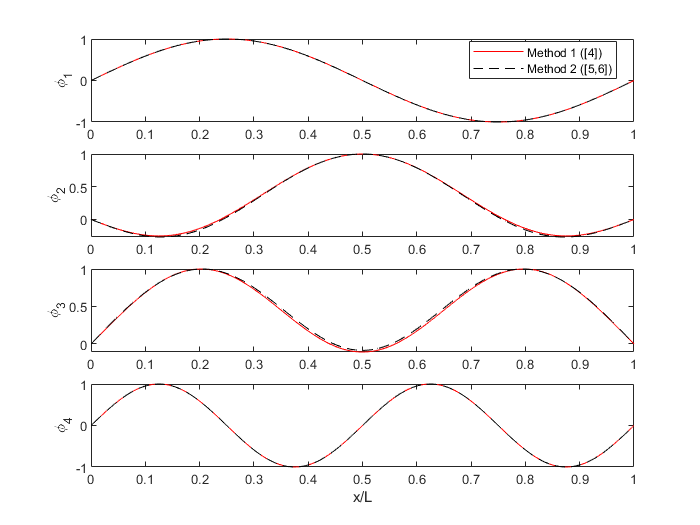

figure
for ii=1:4
    subplot(4,1,ii)
    if ii==1
        plot(Bridge.x,phi1(ii,:),'r',Bridge.x,phi2(ii,:),'k--');
    elseif ii==4
        plot(Bridge.x,phi1(ii,:),'r',Bridge.x,-phi2(ii,:),'k--');
        xlabel('x/L');
    else
        plot(Bridge.x,phi1(ii,:),'r',Bridge.x,phi2(ii,:),'k--');
    end
    if ii==1
        legend('Method 1 ([4])','Method 2 ([5,6])','location','best')
    end
    ylabel(['\phi_',num2str(ii)])
end
set(gcf,'color','w')